ODE45 (수치해석적으로 미방풀기)

y'=2t 를 ode_f1.m으로 만들고

시간 구간 [0,5], y(0)=0 사용

clear
clc
close all

y0 = 0;
[t, y] = ode45('ode_f1', [0,5], y0);
plot(t, y, 'o-')

ODE45 예제2

y'' -3y' + 2'y = 3cos(t)

y(0) = 0, y'(0) = 1

ode45를 이용하기 위한 변형

y1 = y

y2 = y' -> y1'=y2

y'' = y2' = 3y2 - 2y1 + 3cos(t)

ode45를 이용하기 위한 최종 변형식

y1' = y2

y2' = 3y2 - 2y1 + 3cos(t)

위를 함수로 ode_f2으로 만든다

초기값 y(0) = 0, y'(0) = 1 / 시간 구간 [0 1]

clear
clc
close all

[t, y] = ode45('ode_f2', [0,1], [0; 1]);
%[t, y] = ode45(@ode_f2, [0,1], [0; 1]);

figure
plot(t, y(:,1), 'r-') %t와 y간의 그래프
hold

현재 플롯이 유지됨


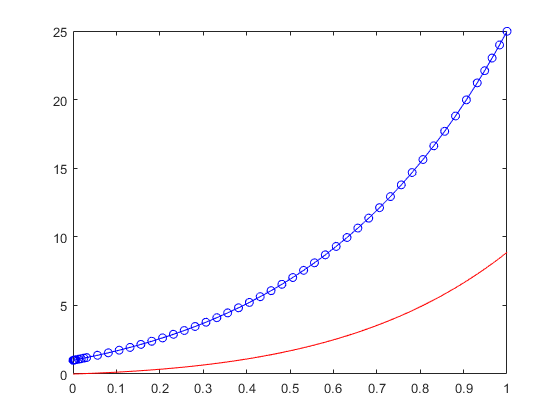

plot(t, y(:,2), 'ob-') %t와 y'간의 그래프